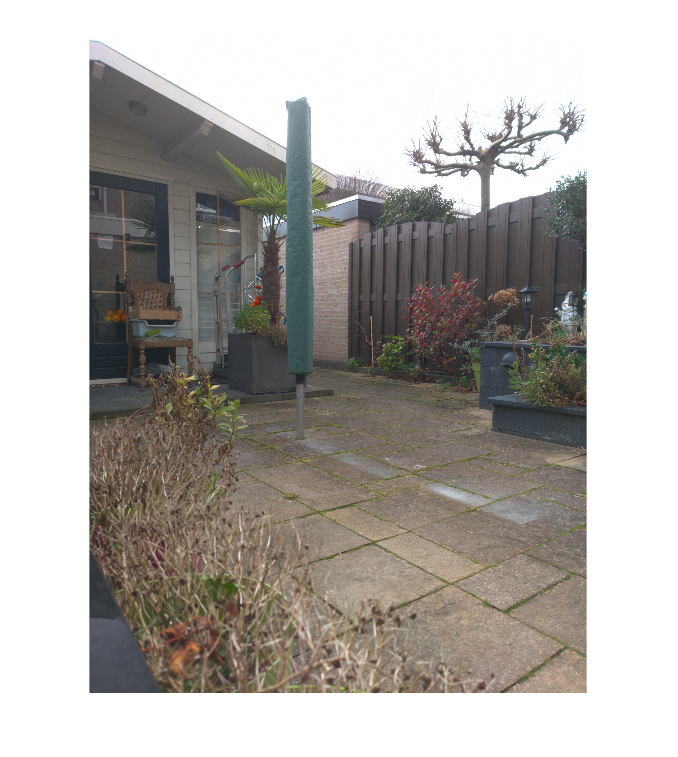

file = 'gardendng';

rot0 = imread(strcat('raw/', file, '0.jpg'));
rot0 = imresize(rot0, 0.5);
rot0 = imrotate(rot0, -90);
imshow(rot0);


imwrite(rot0(9:end-8, 9:end-8, :), strcat('cut/', file, '0.tif'));

for x=45:45:135

deg = num2str(x);

rot = imread(strcat('raw/', file, deg, '.jpg'));
rot = imresize(rot, 0.5);
rot = imrotate(rot, -90);
imshow(rot);

tformEstimate = imregcorr(rot, rot0, 'rigid');

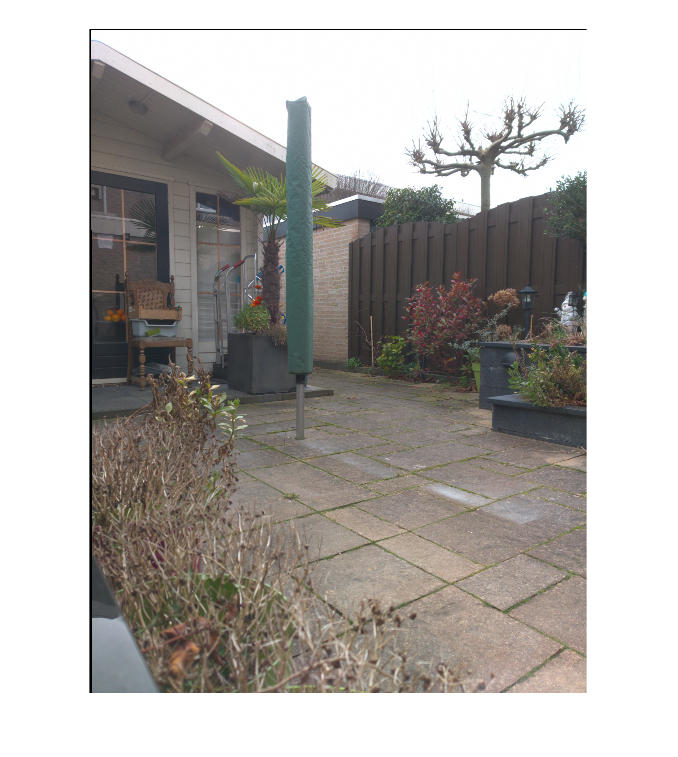

Rfixed = imref2d(size(rot0));
rotreg = imwarp(rot, tformEstimate, 'OutputView', Rfixed);
imshow(rotreg);


imwrite(rotreg(9:end-8, 9:end-8, :), strcat('cut/', file, deg, '.tif'));

end

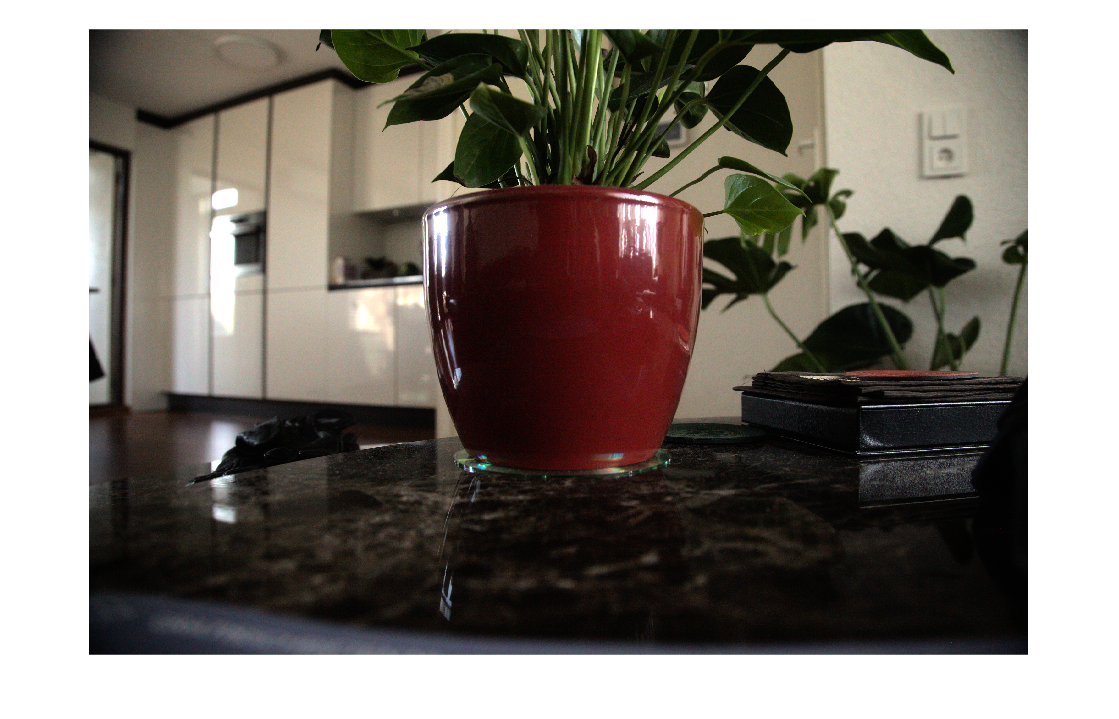

file = 'inside';
deg = num2str(0);
rot = imread(strcat('canoncut/', file, deg, '.tif'));
imshow(2.0 .* rot);